# Wyznania Religijne w Polsce – Wykresy Porównawcze Międzygrupowe (16–25)

========================================================= Dane źródłowe: GUS / Rocznik Statystyczny RP Okres: lata 1947–1998 Ten skrypt generuje 10 DODATKOWYCH wykresów (nr 16–25) koncentrując się na PORÓWNANIACH między grupami wyznaniowymi.

Uruchom po głównym skrypcie wyznania_religijne_15wykresow.m lub osobno – wszystkie dane są tu osadzone. =========================================================

close all; clc;
set(0,'DefaultAxesFontName','Arial');
set(0,'DefaultTextFontName','Arial');
set(0,'DefaultAxesFontSize',11);

colors = [ ...
    0.122 0.467 0.706; ...
    1.000 0.498 0.055; ...
    0.173 0.627 0.173; ...
    0.839 0.153 0.157; ...
    0.580 0.404 0.741; ...
    0.549 0.337 0.294; ...
    0.890 0.467 0.761; ...
    0.498 0.498 0.498; ...
    0.737 0.741 0.133; ...
    0.090 0.745 0.812; ...
    0.682 0.780 0.910; ...
    0.992 0.745 0.435];

fprintf('Generowanie wykresów porównawczych 16–25...\n');

Generowanie wykresów porównawczych 16–25...



% =========================================================

## WYKRES 16

Liczba duchownych w 8 wyznaniach – porównanie w latach 1960 / 1970 / 1980 / 1990 / 1998 (zgrupowany wykres słupkowy) =========================================================

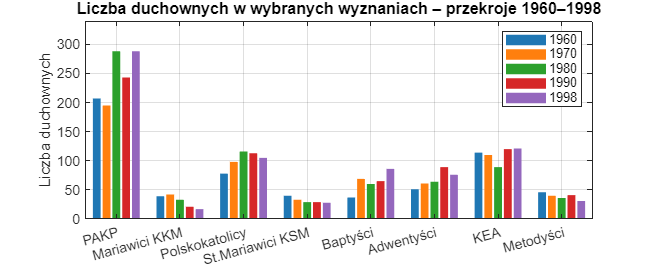

figure('Name','Wykres 16 – Duchowni: Porównanie 8 wyznań w 5 przekrojach',...
    'NumberTitle','off','Units','normalized','Position',[0.03 0.55 0.55 0.40]);

wyznania_labels = {'PAKP','Mariawici KKM','Polskokatolicy','St.Mariawici KSM',...
    'Baptyści','Adwentyści','KEA','Metodyści'};
% Wartości: wiersze = wyznania, kolumny = [1960, 1970, 1980, 1990, 1998]
clergy_matrix = [ ...
    207, 195, 288, 243, 288; ...   % PAKP
    39,  42,  33,  21,  17; ...   % Mariawici KKM
    78,  98, 116, 113, 105; ...   % Polskokatolicy
    40,  33,  29,  29,  28; ...   % St.Mariawici
    37,  69,  60,  65,  86; ...   % Baptyści
    51,  61,  64,  89,  76; ...   % Adwentyści
    114, 110,  89, 120, 121; ...   % KEA
    46,  40,  36,  41,  31];      % Metodyści

hb = bar(clergy_matrix, 'grouped');
group_colors = colors(1:5,:);
for k = 1:5
    hb(k).FaceColor = group_colors(k,:);
    hb(k).EdgeColor = 'none';
end
set(gca,'XTick',1:8,'XTickLabel',wyznania_labels,'XTickLabelRotation',15);
ylabel('Liczba duchownych');
title('Liczba duchownych w wybranych wyznaniach – przekroje 1960–1998',...
    'FontSize',12,'FontWeight','bold');
legend({'1960','1970','1980','1990','1998'},'Location','northeast');
grid on; box on; ylim([0 340]);


% =========================================================

## WYKRES 17

Liczba obiektów kultu – porównanie wyznań (1998) Wykres bąbelkowy / słupkowy z podziałem na grupy wyznaniowe =========================================================

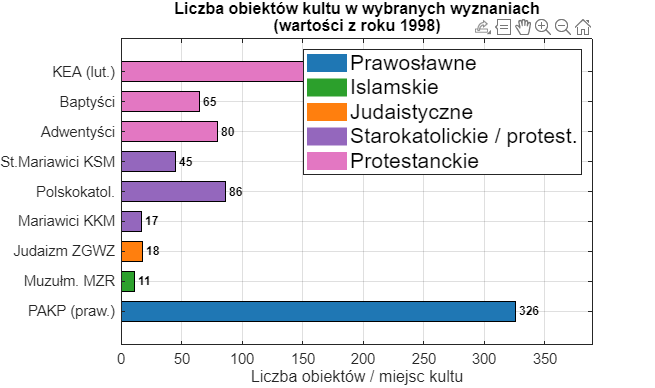

figure('Name','Wykres 17 – Obiekty kultu: Porównanie wyznań (1998)',...
    'NumberTitle','off','Units','normalized','Position',[0.60 0.55 0.38 0.40]);

obj_names = {'PAKP (praw.)','Muzułm. MZR','Judaizm ZGWZ','Mariawici KKM',...
    'Polskokatol.','St.Mariawici KSM','Adwentyści','Baptyści','KEA (lut.)'};
obj_vals_1998 = [326, 11, 18, 17, 86, 45, 80, 65, 277];
% Kolory wg grupy wyznaniowej
obj_colors_idx = [1, 3, 2, 5, 5, 5, 7, 7, 7];

hb = barh(1:9, obj_vals_1998, 0.65);
hb.FaceColor = 'flat';
for k = 1:9
    hb.CData(k,:) = colors(obj_colors_idx(k),:);
end
yticks(1:9); yticklabels(obj_names);
xlabel('Liczba obiektów / miejsc kultu');
title({'Liczba obiektów kultu w wybranych wyznaniach','(wartości z roku 1998)'},...
    'FontSize',12,'FontWeight','bold');
for k = 1:9
    text(obj_vals_1998(k)+3, k, num2str(obj_vals_1998(k)),...
        'VerticalAlignment','middle','FontSize',9,'FontWeight','bold');
end
xlim([0 390]); grid on; box on;
% Legenda grup
patch(NaN,NaN,colors(1,:),'EdgeColor','none','DisplayName','Prawosławne'); %hold on;
patch(NaN,NaN,colors(3,:),'EdgeColor','none','DisplayName','Islamskie');
patch(NaN,NaN,colors(2,:),'EdgeColor','none','DisplayName','Judaistyczne');
patch(NaN,NaN,colors(5,:),'EdgeColor','none','DisplayName','Starokatolickie / protest.');
patch(NaN,NaN,colors(7,:),'EdgeColor','none','DisplayName','Protestanckie');
legend('Location','northeast','FontSize',16);

legend(["", "Prawosławne", "Islamskie", "Judaistyczne", "Starokatolickie / protest.", "Protestanckie"], "FontSize", 16, "Location", "northeast")


% =========================================================

## WYKRES 18

Dynamika liczby członków 4 dużych wyznań protestanckich (1948–1998) Adwentyści, Baptyści, Metodyści, Reformowani =========================================================

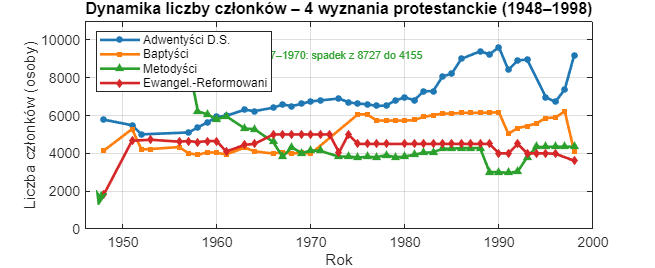

figure('Name','Wykres 18 – Protestanci: Dynamika członków 4 wyznania',...
    'NumberTitle','off','Units','normalized','Position',[0.03 0.08 0.55 0.40]);

adw_y = [1948,1951,1952,1957,1958,1959,1960,1961,1963,1964,1966,1967,...
    1968,1969,1970,1971,1973,1974,1975,1976,1977,1978,1979,1980,1981,1982,...
    1983,1984,1985,1986,1988,1989,1990,1991,1992,1993,1995,1996,1997,1998];
adw_v = [5781,5488,5005,5105,5378,5642,5926,5988,6309,6235,6411,6586,...
    6500,6620,6750,6800,6901,6700,6630,6600,6505,6530,6794,6963,6809,7289,...
    7289,8060,8229,8997,9398,9236,9618,8418,8915,8963,6958,6720,7389,9189];

bapt_y = [1948,1951,1952,1953,1956,1957,1958,1959,1960,1961,1963,1964,...
    1966,1967,1968,1969,1970,1975,1976,1977,1978,1979,1980,1981,1982,1983,...
    1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1994,1995,1996,1997,1998];
bapt_v = [4146,5284,4206,4230,4334,4007,3920,4060,4033,3943,4305,4110,...
    3986,4065,3984,4040,3984,6061,6061,5734,5734,5734,5734,5765,5925,6023,...
    6103,6103,6140,6146,6146,6157,6174,5037,5340,5447,5589,5870,5894,6218,4107];

met_y = [1957,1958,1959,1960,1961,1963,1964,1966,1967,1968,1969,1970,...
    1971,1973,1974,1975,1976,1977,1978,1979,1980,1981,1982,1983,1984,1985,...
    1986,1987,1988,1989,1990,1991,1992,1993,1994,1995,1996,1997,1998];
met_v = [8727,6225,6067,5791,5970,5311,5284,4603,3817,4330,4001,4155,...
    4133,3824,3837,3782,3815,3802,3902,3797,3829,3930,4040,4052,4248,4250,...
    4275,4280,4280,3012,3012,2963,3039,3798,4338,4344,4349,4349,4354];

ref_y = [1948,1951,1953,1956,1957,1958,1959,1960,1961,1963,1964,1966,...
    1967,1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1980,1981,...
    1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1994,1995,...
    1996,1998];
ref_v = [1822,4668,4720,4619,4650,4600,4650,4650,4100,4450,4500,5000,...
    5000,5000,5000,5000,5000,5000,4050,5000,4500,4500,4500,4500,4500,4500,...
    4500,4500,4500,4500,4500,4500,4500,4500,4000,4000,4500,4000,4000,4000,...
    3980,3610];

plot(adw_y, adw_v, '-o', 'Color', colors(1,:),...
    'LineWidth',2,'MarkerSize',3,'MarkerFaceColor',colors(1,:)); hold on;
plot(bapt_y, bapt_v, '-s', 'Color', colors(2,:),...
    'LineWidth',2,'MarkerSize',3,'MarkerFaceColor',colors(2,:));
plot(met_y, met_v, '-^', 'Color', colors(3,:),...
    'LineWidth',2,'MarkerSize',3,'MarkerFaceColor',colors(3,:));
plot(ref_y, ref_v, '-d', 'Color', colors(4,:),...
    'LineWidth',2,'MarkerSize',3,'MarkerFaceColor',colors(4,:));

title('Dynamika liczby członków – 4 wyznania protestanckie (1948–1998)',...
    'FontSize',12,'FontWeight','bold');
xlabel('Rok'); ylabel('Liczba członków (osoby)');
legend({'Adwentyści D.S.','Baptyści','Metodyści','Ewangel.-Reformowani'},...
    'Location','northwest','FontSize',9);
grid on; box on; xlim([1946 2000]); ylim([0 11000]);
xticks(1950:10:2000);
% Adnotacja: wielki wzrost Metodystów
annotation('arrow',[0.155 0.15],[0.285 0.235],'Color',colors(3,:),'LineWidth',1.5);
text(1957.5, 9200, '↓ Metodyści 1957–1970: spadek z 8727 do 4155',...
    'FontSize',8,'Color',colors(3,:));


% =========================================================

## WYKRES 19

Wskaźnik: liczba członków przypadających na 1 duchownego (1998) Porównanie wyznań – kto ma więcej wiernych na księdza? =========================================================

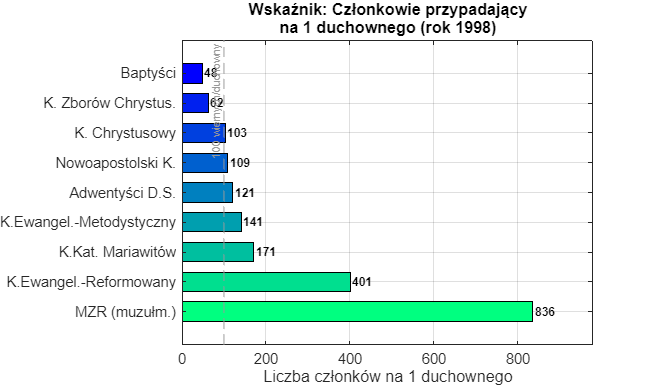

figure('Name','Wykres 19 – Wskaźnik: Członkowie / Duchowny (1998)',...
    'NumberTitle','off','Units','normalized','Position',[0.60 0.08 0.38 0.40]);

ratio_names  = {'K.Ewangel.-Reformowany','K.Kat. Mariawitów','K.Ewangel.-Metodystyczny',...
    'Adwentyści D.S.','Nowoapostolski K.','K. Chrystusowy','Baptyści',...
    'K. Zborów Chrystus.','MZR (muzułm.)'};
ratio_vals   = [401, 171, 141, 121, 109, 103, 48, 62, 836];
% Sort ascending for readable chart
[sv, si] = sort(ratio_vals, 'descend');
snames = ratio_names(si);

hb = barh(1:9, sv, 0.65);
hb.FaceColor = 'flat';
cmap = flipud(winter(9));
for k = 1:9
    hb.CData(k,:) = cmap(k,:);
end
yticks(1:9); yticklabels(snames);
xlabel('Liczba członków na 1 duchownego');
title({'Wskaźnik: Członkowie przypadający','na 1 duchownego (rok 1998)'},...
    'FontSize',12,'FontWeight','bold');
grid on; box on;
for k = 1:9
    text(sv(k)+5, k, num2str(sv(k)),...
        'VerticalAlignment','middle','FontSize',9,'FontWeight','bold');
end
xlim([0 980]);
xline(100,'--','Color',[0.6 0.6 0.6],'LineWidth',1,...
    'Label','100 wiernych/duchowny','LabelHorizontalAlignment','left','FontSize',8);


% =========================================================

## WYKRES 20

Nowoapostolski Kościół vs Adwentyści vs Baptyści Wzrost w latach 1980–1998 – wykresy znormalizowane (bazowy rok 1980 = 100) =========================================================

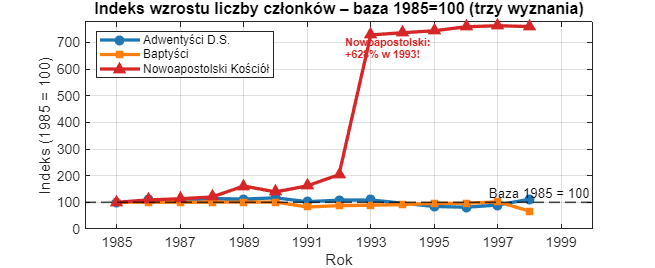

figure('Name','Wykres 20 – Indeks wzrostu (baza 1980=100): 3 wyznania',...
    'NumberTitle','off','Units','normalized','Position',[0.03 0.55 0.55 0.40]);

napost_y = [1965,1970,1974,1975,1976,1982,1983,1984,1985,1986,1987,1988,...
    1989,1990,1991,1992,1993,1994,1995,1996,1997,1998];
napost_v = [321,368,346,348,347,572,620,682,717,781,814,861,...
    1156,997,1160,1462,5218,5277,5330,5438,5466,5443];

% Normalize to 1985 (first common year with reasonable data for all 3)
% Use 1982 as base for Nowoapostolski
base_year = 1985;

% Adwentyści @ 1985
adw_base = adw_v(adw_y == 1985);
bapt_base = bapt_v(bapt_y == 1985);

napost_base_idx = find(napost_y == 1985);
napost_base = napost_v(napost_base_idx);

% Filter to 1985 onwards
adw_mask = adw_y >= 1985;
bapt_mask = bapt_y >= 1985;
napost_mask = napost_y >= 1985;

adw_yn = adw_y(adw_mask);   adw_vn = adw_v(adw_mask)   / adw_base   * 100;
bapt_yn = bapt_y(bapt_mask); bapt_vn = bapt_v(bapt_mask) / bapt_base  * 100;
napost_yn = napost_y(napost_mask); napost_vn = napost_v(napost_mask) / napost_base * 100;

plot(adw_yn, adw_vn, '-o', 'Color', colors(1,:),...
    'LineWidth',2.5,'MarkerSize',5,'MarkerFaceColor',colors(1,:)); hold on;
plot(bapt_yn, bapt_vn, '-s', 'Color', colors(2,:),...
    'LineWidth',2.5,'MarkerSize',5,'MarkerFaceColor',colors(2,:));
plot(napost_yn, napost_vn, '-^', 'Color', colors(4,:),...
    'LineWidth',2.5,'MarkerSize',5,'MarkerFaceColor',colors(4,:));
yline(100,'--k','LineWidth',1.2,'Label','Baza 1985 = 100');
title('Indeks wzrostu liczby członków – baza 1985=100 (trzy wyznania)',...
    'FontSize',12,'FontWeight','bold');
xlabel('Rok'); ylabel('Indeks (1985 = 100)');
legend({'Adwentyści D.S.','Baptyści','Nowoapostolski Kościół'},...
    'Location','northwest','FontSize',9);
grid on; box on; xlim([1984 2000]); ylim([0 780]);
xticks(1985:2:2000);
% Adnotacja wybuchu Nowoapostolskiego
text(1992.2, 680, {'Nowoapostolski:', '+628% w 1993!'},...
    'FontSize',8,'Color',colors(4,:),'FontWeight','bold');


% =========================================================

## WYKRES 21

Rozproszenie (scatter): Liczba członków vs Duchowni w wyznaniach protestanckich w roku 1998 =========================================================

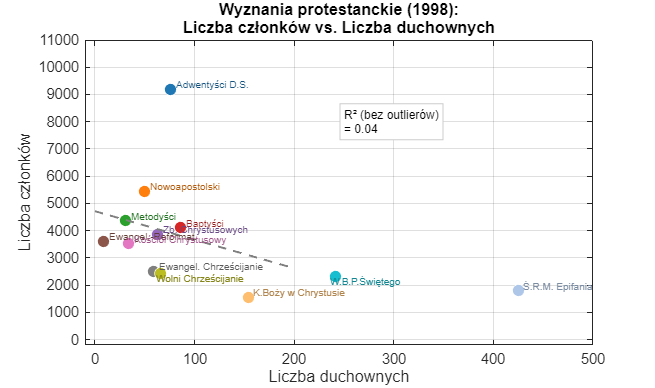

figure('Name','Wykres 21 – Scatter: Członkowie vs Duchowni (1998, protestanci)',...
    'NumberTitle','off','Units','normalized','Position',[0.60 0.55 0.38 0.40]);

sc_names = {'Adwentyści D.S.','Nowoapostolski','Metodyści','Baptyści',...
    'Zb. Chrystusowych','Ewangel.-Reformat.','Kościół Chrystusowy',...
    'Ewangel. Chrześcijanie','Wolni Chrześcijanie','W.B.P.Świętego',...
    'Ś.R.M. Epifania','K.Boży w Chrystusie'};
sc_mem  = [9189, 5443, 4354, 4107, 3875, 3610, 3511, 2500, 2413, 2312, 1791, 1555];
sc_cler = [76,   50,   31,   86,   63,   9,    34,   59,   66,   241,  425,  154];

scatter(sc_cler, sc_mem, 80, colors(1:12,:),...
    'filled','MarkerEdgeColor','white','LineWidth',0.5);
hold on;
% Best-fit line (only main cluster, excl. outliers)
mask_fit = sc_cler < 200;
p = polyfit(sc_cler(mask_fit), sc_mem(mask_fit), 1);
x_fit = linspace(0, 200, 200);
plot(x_fit, polyval(p, x_fit), '--', 'Color', [0.5 0.5 0.5], 'LineWidth',1.5);

% Labels for large points
for k = 1:12
    if sc_mem(k) > 2000 || sc_cler(k) > 100
        offset_x = 5; offset_y = 150;
        if sc_names{k}(1)=='W', offset_x = -5; offset_y = -200; end
        text(sc_cler(k)+offset_x, sc_mem(k)+offset_y, sc_names{k},...
            'FontSize',7.5,'Color', colors(k,:)*0.7);
    end
end
title({'Wyznania protestanckie (1998):','Liczba członków vs. Liczba duchownych'},...
    'FontSize',12,'FontWeight','bold');
xlabel('Liczba duchownych'); ylabel('Liczba członków');
grid on; box on;
xlim([-10 500]); ylim([-200 11000]);
text(250, 8000, sprintf('R² (bez outlierów)\n= %.2f',...
    corr(sc_cler(mask_fit)', sc_mem(mask_fit)')^2),...
    'FontSize',9,'BackgroundColor','white','EdgeColor',[0.8 0.8 0.8]);


% =========================================================

## WYKRES 22

Wyznania mniejszościowe – porównanie trendów liczby synagog, meczetów i obiektów prawosławnych (1948–1998) =========================================================

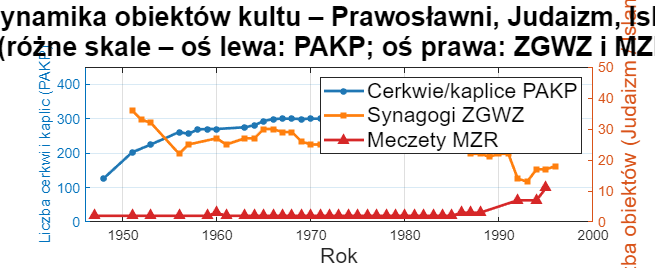

figure('Name','Wykres 22 – Obiekty kultu 3 tradycji: Prawosławni vs Judaizm vs Islam',...
    'NumberTitle','off','Units','normalized','Position',[0.03 0.08 0.55 0.40]);

pakp_obj_y = [1948,1951,1953,1956,1957,1958,1959,1960,1963,1964,1965,1966,...
    1967,1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,1980,...
    1981,1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1995,...
    1996,1997,1998];
pakp_obj_v = [127,202,225,261,256,269,270,270,275,281,293,299,300,300,299,...
    300,300,300,301,301,301,301,301,301,295,295,295,301,301,311,313,313,299,...
    299,313,313,410,410,410,319,325,325,326];

zgwz_obj_y = [1951,1952,1953,1956,1957,1960,1961,1963,1964,1965,1966,1967,...
    1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,1980,1981,...
    1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1994,1995,1996];
zgwz_obj_v = [36,33,32,22,25,27,25,27,27,30,30,29,29,26,25,25,24,24,24,...
    24,24,24,24,24,24,24,24,24,23,23,23,22,22,21,22,22,14,13,17,17,18];

mzr_obj_y = [1947,1951,1953,1956,1959,1960,1961,1963,1964,1965,1966,1967,...
    1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,1980,1981,...
    1982,1983,1984,1985,1986,1987,1988,1992,1994,1995];
mzr_obj_v = [2,2,2,2,2,3,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,...
    2,2,3,3,3,7,7,11];

yyaxis left;
plot(pakp_obj_y, pakp_obj_v, '-o', 'Color', colors(1,:),...
    'LineWidth',2,'MarkerSize',3,'MarkerFaceColor',colors(1,:));
ylabel('Liczba cerkwi i kaplic (PAKP)');
ylim([0 450]);
yyaxis right;
plot(zgwz_obj_y, zgwz_obj_v, '-s', 'Color', colors(2,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(2,:));
hold on;
plot(mzr_obj_y, mzr_obj_v, '-^', 'Color', colors(4,:),...
    'LineWidth',2,'MarkerSize',5,'MarkerFaceColor',colors(4,:));
ylabel('Liczba obiektów (Judaizm / Islam)', 'FontSize', 16);
ylim([0 50]);
title({'Dynamika obiektów kultu – Prawosławni, Judaizm, Islam','(różne skale – oś lewa: PAKP; oś prawa: ZGWZ i MZR)'},...
    'FontSize',20,'FontWeight','bold');
xlabel('Rok', 'FontSize', 16); grid on; box on; xlim([1946 2000]);
xticks(1950:10:2000);
legend({'Cerkwie/kaplice PAKP','Synagogi ZGWZ','Meczety MZR'},...
    'Location','northeast','FontSize',16);


% =========================================================

## WYKRES 23

Wyznania Dalekiego Wschodu – zestawienie poszczególnych organizacji buddyjskich (słupki skumulowane 1984–1998) =========================================================

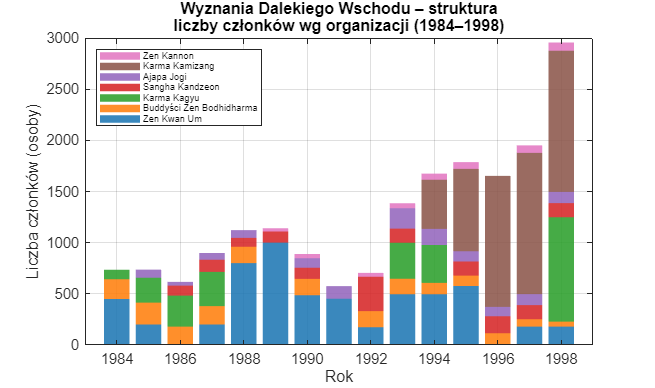

figure('Name','Wykres 23 – Daleki Wschód: Organizacje buddyjskie (skumulowane)',...
    'NumberTitle','off','Units','normalized','Position',[0.60 0.08 0.38 0.40]);

dw_plot_years = 1984:1998;
n_yr = length(dw_plot_years);

% Budowanie macierzy danych przez dopasowanie lat
zen_kwan_y = [1981,1982,1984,1985,1987,1988,1989,1990,1991,1992,1993,1994,1995,1997,1998];
zen_kwan_v = [200,250,450,200,200,800,1000,486,452,174,496,496,576,180,180];

bodhi_y = [1981,1982,1984,1985,1986,1987,1988,1990,1992,1993,1994,1995,1996,1997,1998];
bodhi_v = [187,212,193,214,180,180,160,160,157,151,111,102,115,72,48];

karma_kag_y = [1984,1985,1986,1987,1993,1994,1998];
karma_kag_v = [92,243,302,334,352,370,1020];

sangha_y = [1986,1987,1988,1989,1990,1992,1993,1995,1996,1997,1998];
sangha_v = [98,119,87,109,109,336,138,138,166,138,138];

ajapa_y = [1985,1986,1987,1988,1990,1991,1993,1994,1995,1996,1997,1998];
ajapa_v = [80,37,66,75,93,123,199,158,100,92,107,110];

karma_kam_y = [1994,1995,1996,1997,1998];
karma_kam_v = [480,805,1280,1380,1380];

zen_kannon_y = [1989,1990,1992,1993,1994,1995,1997,1998];
zen_kannon_v = [32,41,38,49,60,66,74,80];

series_y = {zen_kwan_y, bodhi_y, karma_kag_y, sangha_y, ajapa_y, karma_kam_y, zen_kannon_y};
series_v = {zen_kwan_v, bodhi_v, karma_kag_v, sangha_v, ajapa_v, karma_kam_v, zen_kannon_v};
series_names = {'Zen Kwan Um','Buddyści Zen Bodhidharma','Karma Kagyu',...
    'Sangha Kandzeon','Ajapa Jogi','Karma Kamizang','Zen Kannon'};

mat = zeros(length(series_y), n_yr);
for s = 1:length(series_y)
    sy = series_y{s}; sv = series_v{s};
    for yi = 1:n_yr
        ty = dw_plot_years(yi);
        idx = find(sy == ty);
        if ~isempty(idx)
            mat(s, yi) = sv(idx);
        end
    end
end

hb = bar(dw_plot_years, mat', 'stacked', 'EdgeColor','none');
for k = 1:length(series_y)
    hb(k).FaceColor = colors(mod(k-1,12)+1,:);
    hb(k).FaceAlpha = 0.88;
end
title({'Wyznania Dalekiego Wschodu – struktura','liczby członków wg organizacji (1984–1998)'},...
    'FontSize',12,'FontWeight','bold');
xlabel('Rok'); ylabel('Liczba członków (osoby)');
legend(series_names,'Location','northwest','FontSize',7);
grid on; box on; xlim([1983 1999]);
xticks(1984:2:1998);


% =========================================================

## WYKRES 24

Długoterminowe trendy: Zjednoczony Kościół Ewangeliczny (ZKE) vs następcy po rozwiązaniu w 1988 r. Pokazuje konsolidację → rozbicie na wiele wyznań =========================================================

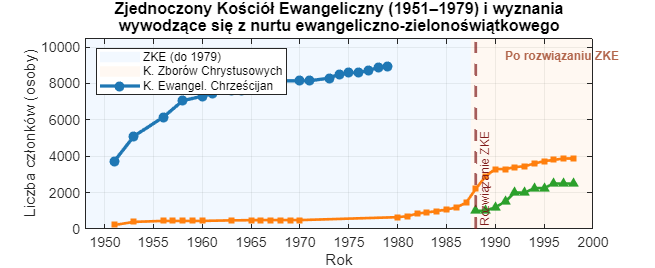

figure('Name','Wykres 24 – ZKE i jego następcy: Konsolidacja vs rozproszenie',...
    'NumberTitle','off','Units','normalized','Position',[0.03 0.55 0.55 0.40]);

zke_y = [1951,1953,1956,1958,1960,1961,1963,1964,1966,1967,1968,1970,...
    1971,1973,1974,1975,1976,1977,1978,1979];
zke_v = [3722,5100,6143,7051,7301,7439,7626,7626,7800,8055,8146,8146,...
    8150,8293,8517,8579,8600,8720,8872,8960];

% Successors that emerged after ZKE dissolved (post-1988)
% Kościół Zielonoświątkowy clergy series (proxy for largest successor)
ziel_duch_y = [1988,1989,1990,1991,1992,1993,1994,1995,1996,1997,1998];
ziel_duch_v = [133,137,143,149,199,202,208,221,250,272,285];

% Kościół Ewangelicznych Chrześcijan - members
kec_y = [1988,1989,1990,1991,1992,1993,1994,1995,1996,1997,1998];
kec_v = [1000,1000,1200,1500,2000,2000,2250,2250,2500,2500,2500];

% Kościół Zborów Chrystusowych
kzch_y = [1951,1953,1956,1957,1958,1959,1960,1963,1965,1966,1967,1968,...
    1969,1970,1980,1981,1982,1983,1984,1985,1986,1987,1988,1989,1990,...
    1991,1992,1993,1994,1995,1996,1997,1998];
kzch_v = [220,390,445,445,445,445,445,475,485,490,490,490,490,490,...
    650,700,850,910,985,1070,1180,1440,2200,2900,3297,3297,3400,3450,...
    3600,3728,3800,3875,3875];

% Timeline shading
xregion1 = [1945 1987.5]; xregion2 = [1987.5 2001];

fill([xregion1(1) xregion1(2) xregion1(2) xregion1(1)],...
    [-500 -500 11000 11000],[0.9 0.95 1],'EdgeColor','none','FaceAlpha',0.5);
hold on;
fill([xregion2(1) xregion2(2) xregion2(2) xregion2(1)],...
    [-500 -500 11000 11000],[1 0.95 0.9],'EdgeColor','none','FaceAlpha',0.5);

plot(zke_y, zke_v, '-o', 'Color', colors(1,:),...
    'LineWidth',2.5,'MarkerSize',5,'MarkerFaceColor',colors(1,:));
plot(kzch_y, kzch_v, '-s', 'Color', colors(2,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(2,:));
plot(kec_y, kec_v, '-^', 'Color', colors(3,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(3,:));

xline(1988,'--','Color',[0.5 0.1 0.1],'LineWidth',2,...
    'Label','Rozwiązanie ZKE','LabelVerticalAlignment','bottom','FontSize',9);

title({'Zjednoczony Kościół Ewangeliczny (1951–1979) i wyznania','wywodzące się z nurtu ewangeliczno-zielonoświątkowego'},...
    'FontSize',12,'FontWeight','bold');
xlabel('Rok'); ylabel('Liczba członków (osoby)');
legend({'ZKE (do 1979)','K. Zborów Chrystusowych','K. Ewangel. Chrześcijan'},...
    'Location','northwest','FontSize',9);
grid on; box on; xlim([1948 2000]); ylim([0 10500]);
xticks(1950:5:2000);
text(1960, 9500,'Okres ZKE','FontSize',9,'Color',[0.3 0.4 0.7],'FontWeight','bold');
text(1991, 9500,'Po rozwiązaniu ZKE','FontSize',9,'Color',[0.7 0.4 0.3],'FontWeight','bold');


% =========================================================

## WYKRES 25

Heatmapa aktywności wyznań – liczba duchownych we wszystkich grupach wyznaniowych w wybranych latach (mapa ciepła) =========================================================

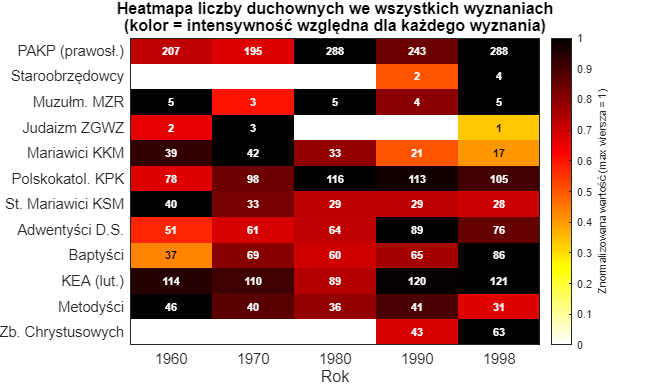

figure('Name','Wykres 25 – Heatmapa: Duchowni we wszystkich wyznaniach',...
    'NumberTitle','off','Units','normalized','Position',[0.60 0.08 0.38 0.40]);

hm_years   = [1960, 1970, 1980, 1990, 1998];
hm_labels  = {'1960','1970','1980','1990','1998'};
hm_orgs    = {'PAKP (prawosł.)','Staroobrzędowcy','Muzułm. MZR','Judaizm ZGWZ',...
    'Mariawici KKM','Polskokatol. KPK','St. Mariawici KSM','Adwentyści D.S.',...
    'Baptyści','KEA (lut.)','Metodyści','Zb. Chrystusowych'};

% Raw clergy numbers matrix [org × year]
hm_data = [ ...
    207, 195, 288, 243, 288;  ... % PAKP
    0,   0,   0,   2,   4;  ... % Staroobrzędowcy (brak wcześniej)
    5,   3,   5,   4,   5;  ... % MZR duchowni
    2,   3,   0,   0,   1;  ... % ZGWZ
    39,  42,  33,  21,  17;  ... % KKM
    78,  98, 116, 113, 105;  ... % KPK
    40,  33,  29,  29,  28;  ... % KSM
    51,  61,  64,  89,  76;  ... % Adwentyści
    37,  69,  60,  65,  86;  ... % Baptyści
    114, 110,  89, 120, 121;  ... % KEA
    46,  40,  36,  41,  31;  ... % Metodyści
    0,   0,   0,  43,  63]; ... % Zb.Chrystusowych
    
% Normalize row-wise for perceptual comparison
hm_norm = zeros(size(hm_data));
for r = 1:size(hm_data,1)
    row_max = max(hm_data(r,:));
    if row_max > 0
        hm_norm(r,:) = hm_data(r,:) / row_max;
    end
end

imagesc(hm_norm);
colormap(flipud(hot));
cb = colorbar;
cb.Label.String = 'Znormalizowana wartość (max wiersza = 1)';
cb.FontSize = 8;

% Add text annotations with actual values
for r = 1:size(hm_data,1)
    for c = 1:size(hm_data,2)
        val = hm_data(r,c);
        if val > 0
            txt_color = 'white';
            if hm_norm(r,c) < 0.5, txt_color = 'black'; end
            text(c, r, num2str(val), 'HorizontalAlignment','center',...
                'VerticalAlignment','middle', 'FontSize',8,...
                'FontWeight','bold', 'Color', txt_color);
        end
    end
end

xticks(1:5); xticklabels(hm_years);
yticks(1:12); yticklabels(hm_orgs);
xlabel('Rok');
title({'Heatmapa liczby duchownych we wszystkich wyznaniach','(kolor = intensywność względna dla każdego wyznania)'},...
    'FontSize',12,'FontWeight','bold');
set(gca,'TickLength',[0 0]);
box on;


% =========================================================

## Podsumowanie

=========================================================

fprintf('\n================================================\n');

fprintf('  WYKRESY PORÓWNAWCZE 16–25 – PODSUMOWANIE\n');

  WYKRESY PORÓWNAWCZE 16–25 – PODSUMOWANIE


fprintf('================================================\n');

fprintf(' Wyk. 16: Duchowni w 8 wyznaniach – 5 przekrojów (grouped bar)\n');

 Wyk. 16: Duchowni w 8 wyznaniach – 5 przekrojów (grouped bar)


fprintf(' Wyk. 17: Obiekty kultu – porównanie 9 wyznań w 1998\n');

 Wyk. 17: Obiekty kultu – porównanie 9 wyznań w 1998


fprintf(' Wyk. 18: Dynamika członków – 4 protestanckie (1948–1998)\n');

 Wyk. 18: Dynamika członków – 4 protestanckie (1948–1998)


fprintf(' Wyk. 19: Wskaźnik: ilu wiernych na 1 duchownego? (1998)\n');

 Wyk. 19: Wskaźnik: ilu wiernych na 1 duchownego? (1998)


fprintf(' Wyk. 20: Indeks wzrostu (baza 1985=100): 3 wyznania\n');

 Wyk. 20: Indeks wzrostu (baza 1985=100): 3 wyznania


fprintf(' Wyk. 21: Scatter: Członkowie vs Duchowni (protestanci 1998)\n');

 Wyk. 21: Scatter: Członkowie vs Duchowni (protestanci 1998)


fprintf(' Wyk. 22: Obiekty kultu – Prawosławni vs Judaizm vs Islam\n');

 Wyk. 22: Obiekty kultu – Prawosławni vs Judaizm vs Islam


fprintf(' Wyk. 23: Daleki Wschód – skumulowane słupki wg organizacji\n');

 Wyk. 23: Daleki Wschód – skumulowane słupki wg organizacji


fprintf(' Wyk. 24: ZKE i następcy – konsolidacja vs rozproszenie\n');

 Wyk. 24: ZKE i następcy – konsolidacja vs rozproszenie


fprintf(' Wyk. 25: Heatmapa duchownych – wszystkie wyznania i lata\n');

 Wyk. 25: Heatmapa duchownych – wszystkie wyznania i lata


fprintf('\nŹródło: GUS / Rocznik Statystyczny RP, dane 1947–1998\n');


Źródło: GUS / Rocznik Statystyczny RP, dane 1947–1998


fprintf('================================================\n');